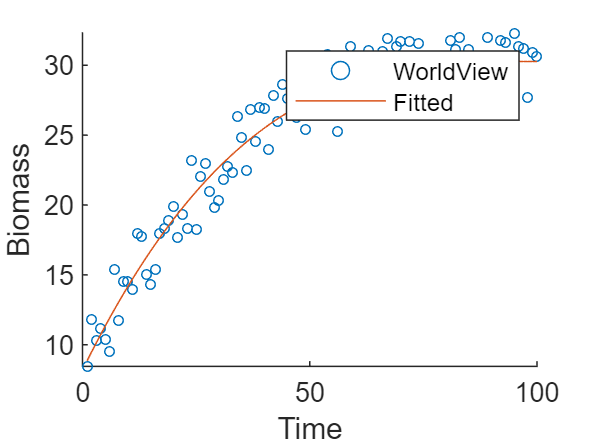

bbb = [8.446636526097006, 11.794696011499086, 10.29138556870631, 11.166033666375156, 10.34533584981136, 9.54016600345589, 15.362740219759162, 11.72788663377243, 14.517297409093644, 14.50608457223181, 13.941252737742476, 17.949098308739316, 17.767933928610994, 14.990742413832795, 14.323627768482414, 15.368834507980038, 17.992792399806795, 18.288471865377293, 18.88764089643893, 19.884381839159524, 17.641529138741507, 19.293119948461108, 18.319650665353194, 23.16165321376446, 18.271402103445617, 22.011939072836647, 22.934042759629776, 20.956623522740855, 19.818214480242347, 20.33411585770689, 21.843535562690693, 22.723625981595188, 22.289522261346868, 26.341974594825047, 24.820287437501044, 22.485909136468415, 26.843102115833553, 24.510088839627148, 26.98464799358942, 26.902822479177665, 23.964572552895536, 27.812979474502843, 25.981607509231086, 28.65741701862605, 27.59615725755279, 28.756814762677518, 26.275568946690733, 26.731287613625252, 25.385141440093296, 30.319548409820804, 28.758243773168843, 26.73161125991457, 28.657194831453424, 30.75460504368619, 29.464171553511555, 25.26671926293773, 26.450773885168566, 28.65626843258075, 31.347677832819, 27.74737989892182, 28.123983238703467, 28.39014358992146, 31.063200984690443, 30.362621064443577, 28.178381824953036, 30.96255142166161, 31.879968121587012, 26.864427716341865, 31.339212581254444, 31.68137881678223, 27.28669645861859, 31.707565452610947, 26.527276858010957, 31.52426342381407, 29.673515267619603, 29.57093165590446, 28.214618789355583, 27.916377948129227, 26.786093335108713, 27.23986005265474, 31.752839564634925, 31.134405118144265, 31.984441633529343, 28.50122128121851, 31.12901179840867, 27.44094404169039, 29.60179840764783, 30.17609162028321, 32.016123949609074, 28.63883449621532, 29.8193007803203, 31.805876682739097, 31.64620503665351, 29.621849172390895, 32.306035422527415, 31.369412947529835, 31.212095500311186, 27.682238573855663, 30.903318269108535, 30.593383552767293];
scatter(x,bbb,10);
hold on;
plot(fittedmodel(x));
xlabel('Time');
ylabel('Biomass')

p0=0.5;
k=30;
r=5;
q=0.05; 
t=linspace(0,25,100);

p_u=q*k*p0*exp(q*r*t);
p_l=q*k+p0*(exp(q*r*t)-1);

p=p_u./p_l/q;
hold on;
% plot(x,p);
legend('WorldView','Fitted')